Per prima cosa definiamo quante sono le coordinate generalizzate del robot:

n=2 

n = 2

**Ricorda che la formula che utilizziamo è la seguente:**


$$T_i(q)=\frac{1}{2}m_i \left(V_{cm_i}^i\right)^T V^i_{cm_i} +\frac{1}{2}\left(\omega^i_i\right)^TI_i \ \omega_i^i$$


dove il $V_{cm_i}^w$ indica la velocità del centro di massa del frame i rispetto il frame i e dove:

Poi dobbiamo definire tutte le variabili simboliche di nostro utilizzo:

q = sym('q', [n, 1]);
for i=1:n
    nomeVariabile = ['q' num2str(i)];
    assignin('base', nomeVariabile,q(i,1));
end

L = sym('l', [n, 1]);
for i=1:n
    nomeVariabile = ['l' num2str(i)];
    assignin('base', nomeVariabile,L(i,1));
end

%inertia matrix for each link
I = sym('Ic', [3, 3, n]);
for i=1:n
    I(1,1,i)=sym(['Ic' num2str(i) 'xx']);I(1,2,i)=sym(['Ic' num2str(i) 'xy']); I(1,3,i)=sym(['Ic' num2str(i) 'xz']);
    I(2,1,i)=sym(['Ic' num2str(i) 'yx']);I(2,2,i)=sym(['Ic' num2str(i) 'yy']); I(2,3,i)=sym(['Ic' num2str(i) 'yz']);
    I(3,1,i)=sym(['Ic' num2str(i) 'zx']);I(3,2,i)=sym(['Ic' num2str(i) 'zy']); I(3,3,i)=sym(['Ic' num2str(i) 'zz']);
end

m = sym('m', [n, 1]);
for i=1:n
    nomeVariabile = ['m' num2str(i)];
    assignin('base', nomeVariabile,m(i,1));
end

pcx = sym('pcx', [1,n]);
for i=1:n
    nomeVariabile = ['pcx' num2str(i)];
    assignin('base', nomeVariabile,pcx(1,i));
end
pcy = sym('pcy', [1,n]);
for i=1:n
    nomeVariabile = ['pcy' num2str(i)];
    assignin('base', nomeVariabile,pcy(1,i));
end
pcz = sym('pcz', [1,n]);
for i=1:n
    nomeVariabile = ['pcz' num2str(i)];
    assignin('base', nomeVariabile,pcz(1,i));
end

pcz=subs(pcz,pcz,zeros(1,n));  % da cancellare se si vogliono fare calcoli con pcz

com=[pcx;pcy;pcz]

$$com = \left(\begin{array}{cc} {\mathrm{pcx}}_{1} & {\mathrm{pcx}}_{2}\\ {\mathrm{pcy}}_{1} & {\mathrm{pcy}}_{2}\\ {\mathrm{pcz}}_{1} & {\mathrm{pcz}}_{2} \end{array}\right)$$

Adesso dobbiamo notare che molto spesso ci sono delle condizioni che semplificano la posizione del centro di massa.

**When the center of mass is located on the kinematics axis of the links **we can introduce other variables in order to characterize well the position of the center of mass. 

D = sym('dc', [n, 1]);
for i=1:n
    nomeVariabile = ['dc' num2str(i)];
    assignin('base', nomeVariabile,D(i,1));
end

**Corretta assegnazione delle variabili simboliche rispetto il nostro esercizio ( a mano ) **

Purtroppo come assegnare i parametri dc alle variabili del vettore com **va fatto a mano,** perche ci sono troppe complicazioni nel farlo in matlab e si rischia di sbagliare.

**POSIZIONI DEI CENTRI DI MASSA dei link i rispetto il FRAME i **

In questo caso la situazione  opposta rispetto a quella considerata normalmente, in generale le quantità dc vanno dal centro di massa del link i al frame i 

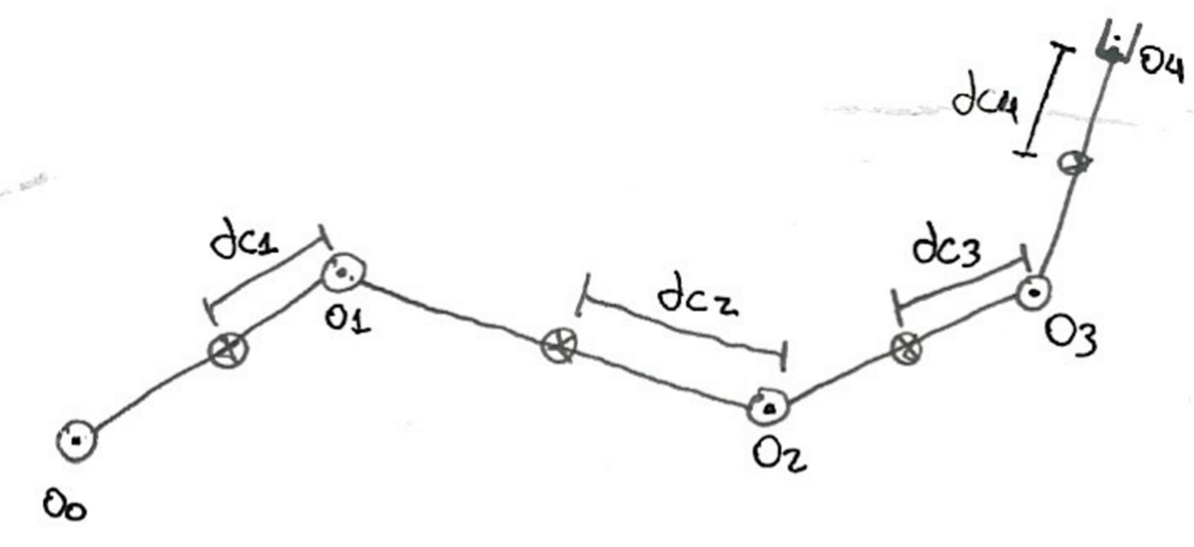

**Assegnazione della posizione del centro di massa del link i rispetto il frame i**

%assegnamo la prima posizione del centro di massa: 
%com(1,1)=0;   %pcx1
%com(2,1)=0;     %pcy1      
%com(3,1)=0;                 %pcz1         %era zero e rimane zero 

%assegnamo la seconda posizione del centro di massa:   
%com(1,2)=;   %pcx2
com(2,2)=0;    %pcy2      
com(3,2)=0;                           %pcz2         %era zero e rimane zero 

% %assegnamo la terza posizione del centro di massa:
% com(1,3)=-l3+dc3;      %pcx3
% com(2,3)=0;       %pcy3
% com(3,3)=0;                                         %pcz3       %era zero e rimane zero 

%assegnamo la quarta posizione del centro di massa:
%com(1,4)=l1*(cos(q1))+l2*cos(q2)+l3*cos(q3)+dc4*cos(q4);        %pcx4
%com(2,4)=l1*(sin(q1))+l2*sin(q2)+l3*sin(q3)+dc4*sin(q4);        %pcy4
%com(3,4)=0;                                                     %pcz4       %era zero e rimane zero 

com

$$com = \left(\begin{array}{cc} {\mathrm{pcx}}_{1} & {\mathrm{pcx}}_{2}\\ {\mathrm{pcy}}_{1} & 0\\ {\mathrm{pcz}}_{1} & 0 \end{array}\right)$$

**Configurazione delle matrici di inerzia:**

- **Joint rotazionali, nessuna modifica, lasciala cosi numerica**

- **joint prismatici:**

**                - Se non è preceduto da nessun Joint rotazionale allora impostare la sua matrice di inerzia =0**

**                - Se è preceduto da un joint rotazionale lasicala cosi numerica**

                    ricordando che il contirbuto rotazionale all' energia cinetica di questo joint prismatico è dattato dalla                           

                    velocità angolare del/dei joint rotazionali precedenti ad esso    

%I(:,:,1)=zeros(n,n); % se il primo joint è prismatico 
%pezzo utilizzato per rendere la matrice di inerzia diagonale.
I(1,2,2)=0;
I(2,1,2)=0;
I(1,3,2)=0;
I(3,1,2)=0;
I(3,2,2)=0;
I(2,3,2)=0;
I

$$\left(\begin{array}{ccc} \mathrm{Ic1xx} & \mathrm{Ic1xy} & \mathrm{Ic1xz}\\ \mathrm{Ic1yx} & \mathrm{Ic1yy} & \mathrm{Ic1yz}\\ \mathrm{Ic1zx} & \mathrm{Ic1zy} & \mathrm{Ic1zz} \end{array}\right)$$

$$\left(\begin{array}{ccc} \mathrm{Ic2xx} & 0 & 0\\ 0 & \mathrm{Ic2yy} & 0\\ 0 & 0 & \mathrm{Ic2zz} \end{array}\right)$$

**calcolo delle Denavit-Hartemberg Matrices**

%DH_table
DH_table=[-pi/2 0 l1 q1; 0  l2 0  q2]

$$DH\_table = \left(\begin{array}{cccc} -\frac{\pi }{2} & 0 & l_{1} & q_{1}\\ 0 & l_{2} & 0 & q_{2} \end{array}\right)$$

syms a alpha tetha d real;
DH_param=[alpha a d tetha];

DH_MAT=[cos(tetha) -cos(alpha)*sin(tetha) sin(alpha)*sin(tetha)   a*cos(tetha);
        sin(tetha)  cos(alpha)*cos(tetha) -sin(alpha)*cos(tetha)  a*sin(tetha);
        0           sin(alpha)              cos(alpha)                 d      ;
        0               0                        0                     1      ];

Rot_matrices=sym('Rot_matrices',[3,3,n]);
Pos_vectors=sym('Pos_vectors',[3,1,n]);
DH_matrices=sym('DH_matrices',[4,4,n]);
for i=1:n
    nomeVariabile = ['R' num2str(i-1)  num2str(i)];
    nomeVariabile1= ['p' num2str(i-1)  num2str(i)];
    DH_MAT_to_sub=subs(DH_MAT(1:3,1:3),DH_param,DH_table(i,:));
    DH_mat_to_sub_pos=subs(DH_MAT(1:3,4),DH_param,DH_table(i,:));
    DH_matrices(:,:,i)=subs(DH_MAT(:,:),DH_param,DH_table(i,:));
    assignin('base', nomeVariabile,DH_MAT_to_sub);
    assignin('base', nomeVariabile1,DH_mat_to_sub_pos);
    Rot_matrices(:,:,i)=DH_MAT_to_sub;
    Pos_vectors(:,i)=DH_mat_to_sub_pos;
end
Rot_matrices % il primo elemento è R01 il secondo R12 eccedera

$$\left(\begin{array}{ccc} \cos\left(q_{1}\right) & 0 & -\sin\left(q_{1}\right)\\ \sin\left(q_{1}\right) & 0 & \cos\left(q_{1}\right)\\ 0 & -1 & 0 \end{array}\right)$$

$$\left(\begin{array}{ccc} \cos\left(q_{2}\right) & -\sin\left(q_{2}\right) & 0\\ \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

%p01 distanza fra origine di F0 e origine di F1
%p12 distanza fra origine di F1 e origine di F2
Pos_vectors % il primo elemento è p01 il secondo p12 eccedera

$$\left(\begin{array}{c} 0\\ 0\\ l_{1} \end{array}\right)$$

$$\left(\begin{array}{c} l_{2}\,\cos\left(q_{2}\right)\\ l_{2}\,\sin\left(q_{2}\right)\\ 0 \end{array}\right)$$

Ora che abbiamo tutte le posizioni procediamo con il **calcolo dell' energia cinetica**.

%components of kinetic energy:
t = sym('T', [n,1]);
qd = sym('qd', [n, 1]);
for i=1:n
    nomeVariabile = ['qd' num2str(i)];
    assignin('base', nomeVariabile,qd(i,1));
end


Ricorda che:


$$T_i(q)=\frac{1}{2}m_i \left(V_{cm_i}^i\right)^T V^i_{cm_i} +\frac{1}{2}\left(\omega^i_i\right)^TI_i \ \omega_i^i$$


dove il $V_{cm_i}^w$ indica la velocità del centro di massa del frame i rispetto il frame i  e dove:


$$\omega^i_i=\left(R_i^{ i-1}(q_i) \right)^T \left( \omega_{i-1}^{i-1} +\omega_i\right)$$


dove $\omega_i$ è la velocità angolare data dal joint i (che è un vettore attaccato al frame i-1) la potremmo scirvere come $\omega^{i-1}_{joint _i}$=$\omega_i z^{i-1}_{i-1}$ ed è praticamente la stessa cosa del mooving frame, infatti il vettore $z_{i-1}^{i-1}$ è sempre ugale a $(0 \ 0 \ 1 )^T$. quindi posso scrivere $\omega_i=\omega_i^{i-1}$, ovvero contirbuito del joint i espresso nel frame i-1.

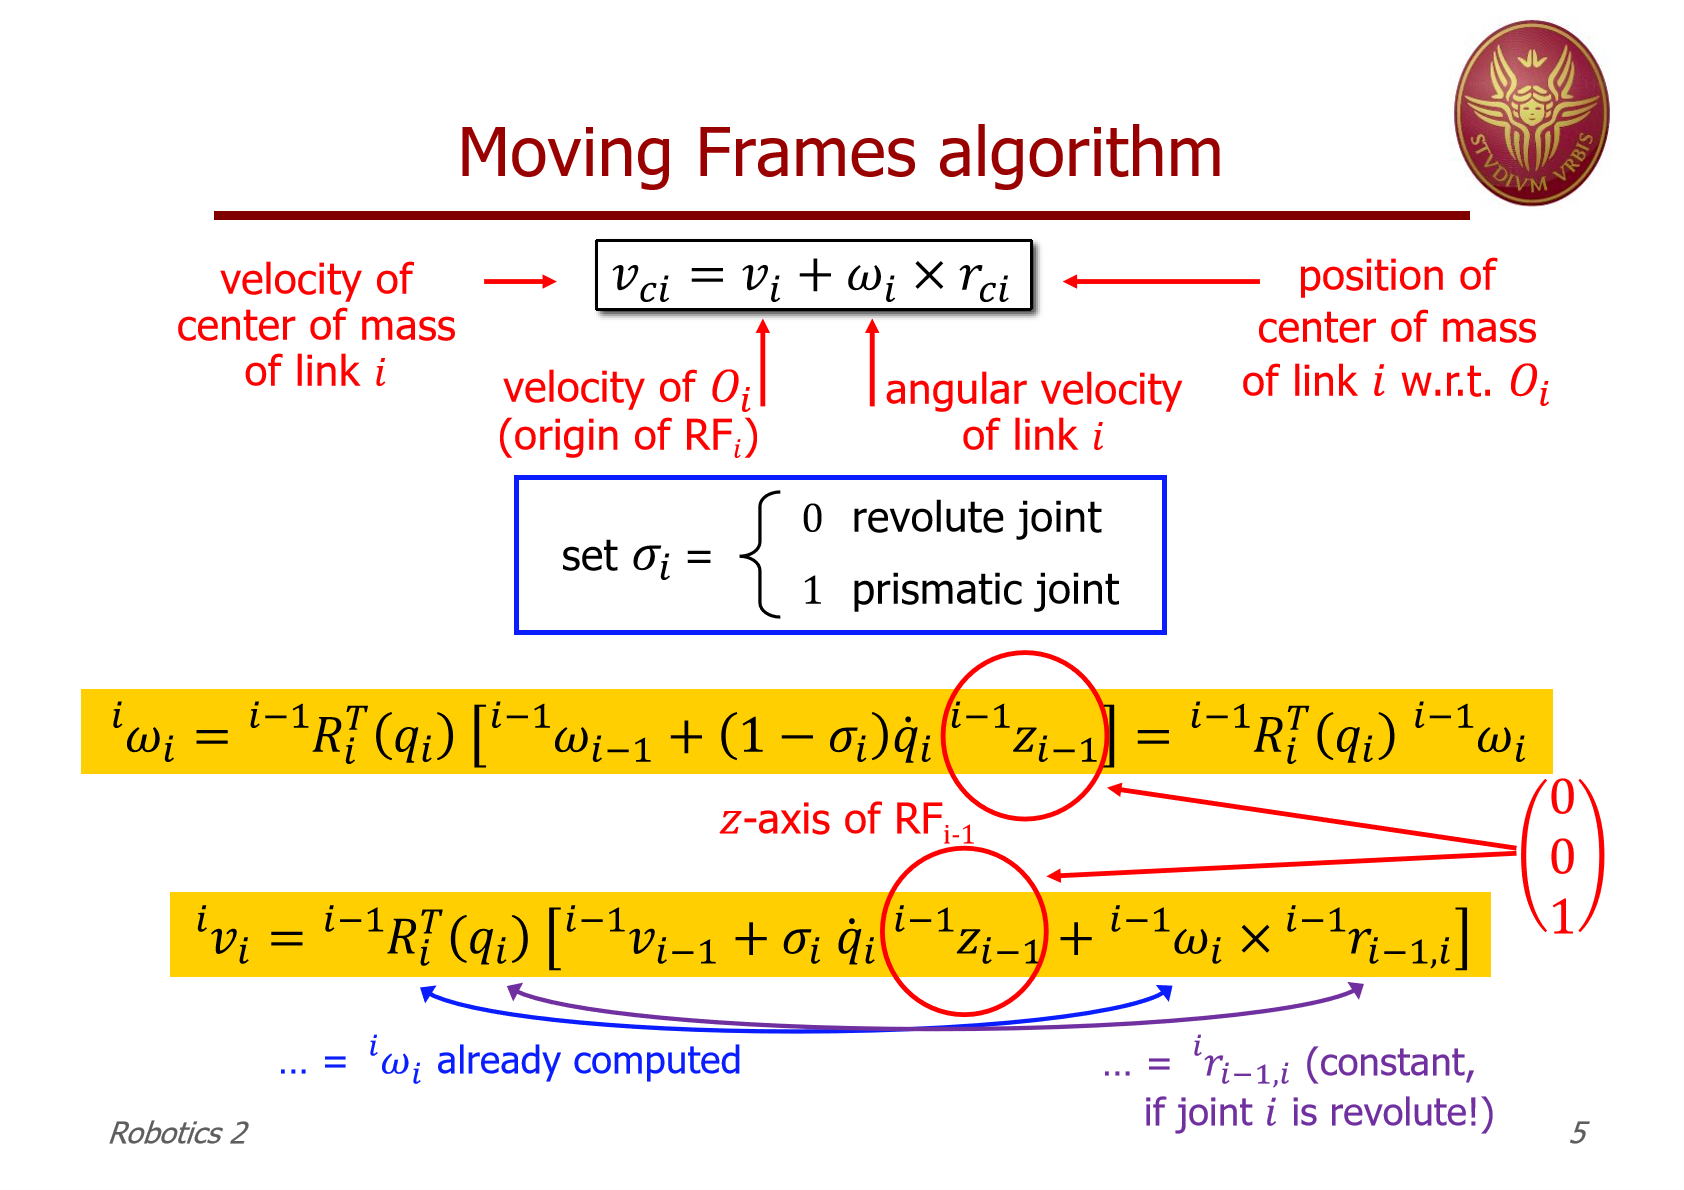

dove $r^{i-1}_{i-1,i}$ è il vettore che connette l' origine del frame i-1 con l' oringe del frame i espresso nel frame i-1.

**Tipo di joint**

Tipo_di_joint=['r','r'];
if(size(Tipo_di_joint)~=n)
    error('Hai sbgalito a inserire il tipo dei joint')
end

**mooving frames algoritmh**

%inizializzazione
omegas=[];
velocities=[];
velocities_cm=[];

omega_world=[0;0;0];velocity_world=[0;0;0];

omegas=[omegas,omega_world];
velocities=[velocities,velocity_world];

for i=1:n
    if (Tipo_di_joint(1,i)=='p')
        sigma=1;
    else
        sigma=0;
    end
    omega=transpose(Rot_matrices(:,:,i))*( omegas(:,i)+(1-sigma)*qd(i,1)*[0;0;1]);
    omegas=[omegas,omega];
end

for i=1:n
    if (Tipo_di_joint(1,i)=='p')
        sigma=1;
    else
        sigma=0;
    end
    vel=transpose(Rot_matrices(:,:,i))*(velocities(:,i)+sigma*qd(i,1)*[0;0;1])  + transpose(Rot_matrices(:,:,i))*cross(( omegas(:,i)+(1-sigma)*qd(i,1)*[0;0;1]) ,Pos_vectors(:,i) )   ;
    velocities=[velocities,vel];
end

omegas

$$omegas = \left(\begin{array}{ccc} 0 & 0 & -{\mathrm{qd}}_{1}\,\sin\left(q_{2}\right)\\ 0 & -{\mathrm{qd}}_{1} & -{\mathrm{qd}}_{1}\,\cos\left(q_{2}\right)\\ 0 & 0 & {\mathrm{qd}}_{2} \end{array}\right)$$

velocities

$$velocities = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & l_{2}\,{\mathrm{qd}}_{2}\,{\cos\left(q_{2}\right)}^{2}+l_{2}\,{\mathrm{qd}}_{2}\,{\sin\left(q_{2}\right)}^{2}\\ 0 & 0 & l_{2}\,{\mathrm{qd}}_{1}\,\cos\left(q_{2}\right) \end{array}\right)$$

for i=1:n
   vel_cm=simplify( velocities(:,i+1)+cross(omegas(:,i+1),com(:,i)));
   velocities_cm=[velocities_cm,vel_cm];
end
velocities_cm

$$velocities\_cm = \left(\begin{array}{cc} -{\mathrm{pcz}}_{1}\,{\mathrm{qd}}_{1} & 0\\ 0 & {\mathrm{qd}}_{2}\,\left(l_{2}+{\mathrm{pcx}}_{2}\right)\\ {\mathrm{pcx}}_{1}\,{\mathrm{qd}}_{1} & {\mathrm{qd}}_{1}\,\cos\left(q_{2}\right)\,\left(l_{2}+{\mathrm{pcx}}_{2}\right) \end{array}\right)$$

%simplify(R01*R12*R23*velocities_cm(:,3))

Come puoi perfettamente vedere attraverso i moving frame consideri le velocità del centro di massa i rispetto il frame i 

**Calcolo energia cinetica**

%components of kinetic energy:
t = sym('T', [n,1]);
qd = sym('qd', [n, 1]);
for i=1:n
    nomeVariabile = ['qd' num2str(i)];
    assignin('base', nomeVariabile,qd(i,1));
end

for i=1:n
    t(i,1)=1/2*m(i,1)*transpose(velocities_cm(:,i))*velocities_cm(:,i)+1/2*transpose(omegas(:,i+1))*I(:,:,i)*omegas(:,i+1);
end
t

$$t = \left(\begin{array}{c} \frac{m_{1}\,{{\mathrm{pcx}}_{1}}^{2}\,{{\mathrm{qd}}_{1}}^{2}}{2}+\frac{m_{1}\,{{\mathrm{pcz}}_{1}}^{2}\,{{\mathrm{qd}}_{1}}^{2}}{2}+\frac{\mathrm{Ic1yy}\,{{\mathrm{qd}}_{1}}^{2}}{2}\\ \frac{\mathrm{Ic2zz}\,{{\mathrm{qd}}_{2}}^{2}}{2}+\frac{m_{2}\,{{\mathrm{qd}}_{2}}^{2}\,{\left(l_{2}+{\mathrm{pcx}}_{2}\right)}^{2}}{2}+\frac{\mathrm{Ic2yy}\,{{\mathrm{qd}}_{1}}^{2}\,{\cos\left(q_{2}\right)}^{2}}{2}+\frac{\mathrm{Ic2xx}\,{{\mathrm{qd}}_{1}}^{2}\,{\sin\left(q_{2}\right)}^{2}}{2}+\frac{m_{2}\,{{\mathrm{qd}}_{1}}^{2}\,{\cos\left(q_{2}\right)}^{2}\,{\left(l_{2}+{\mathrm{pcx}}_{2}\right)}^{2}}{2} \end{array}\right)$$


$$T_i(q)=\frac{1}{2}m_i \left(V_{cm_i}^i\right)^T V^i_{cm_i} +\frac{1}{2}\left(\omega^i_i\right)^TI_i \ \omega_i^i$$


%disp('t semplificato');
%simplify(expand(t))


T=t(1,1);
for i=2:n
    T=T+t(i,1);
end
T=simplify(T)

$$T = \frac{\mathrm{Ic1yy}\,{{\mathrm{qd}}_{1}}^{2}}{2}+\frac{\mathrm{Ic2zz}\,{{\mathrm{qd}}_{2}}^{2}}{2}+\frac{m_{2}\,{{\mathrm{qd}}_{2}}^{2}\,{\left(l_{2}+{\mathrm{pcx}}_{2}\right)}^{2}}{2}+\frac{m_{1}\,{{\mathrm{pcx}}_{1}}^{2}\,{{\mathrm{qd}}_{1}}^{2}}{2}+\frac{m_{1}\,{{\mathrm{pcz}}_{1}}^{2}\,{{\mathrm{qd}}_{1}}^{2}}{2}+\frac{\mathrm{Ic2yy}\,{{\mathrm{qd}}_{1}}^{2}\,{\cos\left(q_{2}\right)}^{2}}{2}+\frac{\mathrm{Ic2xx}\,{{\mathrm{qd}}_{1}}^{2}\,{\sin\left(q_{2}\right)}^{2}}{2}+\frac{m_{2}\,{{\mathrm{qd}}_{1}}^{2}\,{\cos\left(q_{2}\right)}^{2}\,{\left(l_{2}+{\mathrm{pcx}}_{2}\right)}^{2}}{2}$$

Adesso dobbiamo ricavare la matrice M:


$$T(q)=\dot{q}^T M(q)\dot{q}$$


M(1,1)=simplify(diff(T,qd1,2));
M(2,2)=simplify(diff(T,qd2,2));
%M(3,3)=simplify(diff(T,qd3,2));
%M(4,4)=simplify(diff(T,qd4,2));
M(2,1)=simplify(diff(diff(T,qd1),qd2));
%M(3,1)=simplify(diff(diff(T,qd1),qd3));
%M(4,1)=simplify(diff(diff(T,qd1),qd4));
%M(3,2)=simplify(diff(diff(T,qd2),qd3));
%M(4,2)=simplify(diff(diff(T,qd2),qd4));
%M(4,3)=simplify(diff(diff(T,qd3),qd4));

%M è simmetrica quindi:
M(1,2)=M(2,1);
%M(1,3)=M(3,1);
%M(1,4)=M(4,1);
%M(2,3)=M(3,2);
%M(2,4)=M(4,2);
%M(3,4)=M(4,3);

MM=M

$$MM = \left(\begin{array}{cc} \mathrm{Ic1yy}+m_{1}\,{{\mathrm{pcx}}_{1}}^{2}+m_{1}\,{{\mathrm{pcz}}_{1}}^{2}+\mathrm{Ic2yy}\,{\cos\left(q_{2}\right)}^{2}+\mathrm{Ic2xx}\,{\sin\left(q_{2}\right)}^{2}+m_{2}\,{\cos\left(q_{2}\right)}^{2}\,{\left(l_{2}+{\mathrm{pcx}}_{2}\right)}^{2} & 0\\ 0 & \mathrm{Ic2zz}+m_{2}\,{\left(l_{2}+{\mathrm{pcx}}_{2}\right)}^{2} \end{array}\right)$$

syms a1 a2 a3 a4 a5;

M=[a1+(a2+a4)*cos(q2)^2+a3*sin(q2)^2 0 ; 0 a5]

$$M = \left(\begin{array}{cc} \left(a_{2}+a_{4}\right)\,{\cos\left(q_{2}\right)}^{2}+a_{3}\,{\sin\left(q_{2}\right)}^{2}+a_{1} & 0\\ 0 & a_{5} \end{array}\right)$$

Print utili:

Posizioni dei frame della tabella

D=DH_matrices(:,:,1);
disp("Posizione dell'origine del frame 1 rispetto l' orgine");

Posizione dell'origine del frame 1 rispetto l' orgine


DH_matrices(1:3,4,1)

$$ans = \left(\begin{array}{c} 0\\ 0\\ l_{1} \end{array}\right)$$

Nota che in base a come hai definito la posizione del centro di massa DEL LINK 1 ti basta **sostituire a l1** il suo valore rispetto l' orgine per avere la posizione del centro di massa rispetto l 'origne.

Posizioni=sym('Posizioni',[3,n]);
for i=1:n
    D=1;
    for j=1:i
        D=simplify(D*DH_matrices(:,:,j));
    end
    disp(["Posizione dell'origine del frame " num2str(i) " rispetto l' orgine"]);
    Posizioni(:,i)=D(1:3,4);
    D(1:3,4)
end

    "Posizione dell'origine del frame "    "1"    " rispetto l' orgine"



$$ans = \left(\begin{array}{c} 0\\ 0\\ l_{1} \end{array}\right)$$

    "Posizione dell'origine del frame "    "2"    " rispetto l' orgine"



$$ans = \left(\begin{array}{c} l_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ l_{1}-l_{2}\,\sin\left(q_{2}\right) \end{array}\right)$$

Nota che in base a come hai definito la posizione del centro di massa DEL LINK i ti basta **sostituire a li** il suo valore rispetto il **frame precednte** per avere la posizione del centro di massa rispetto l 'origne.

**Per ricavare la velocità di un centro di massa ripsetto l' origine puoi fare la derivata della posizione**

Velocita=sym('Velocita',[3,n]);
for i=1:n
    vels=0;
    for j=1:i
        vels=simplify(vels+diff(Posizioni(:,i),q(j,1))*qd(j,1));
    end
    Velocita(:,i)=vels;
    disp(["Velocità dell'origine del frame " num2str(i) " rispetto l' orgine"]);
    vels
end

    "Velocità dell'origine del frame "    "1"    " rispetto l' orgine"



$$vels = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

    "Velocità dell'origine del frame "    "2"    " rispetto l' orgine"



$$vels = \left(\begin{array}{c} -l_{2}\,{\mathrm{qd}}_{1}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)-l_{2}\,{\mathrm{qd}}_{2}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ l_{2}\,{\mathrm{qd}}_{1}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-l_{2}\,{\mathrm{qd}}_{2}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ -l_{2}\,{\mathrm{qd}}_{2}\,\cos\left(q_{2}\right) \end{array}\right)$$

Adesso verifichiamo le velocità dei centri di massa rispetto l' origine ottenute attraverso i moving frames

%"Velocità del centro di massa  1 rispetto l' orgine"
simplify(R01*velocities_cm(:,1))

$$ans = \left(\begin{array}{c} -{\mathrm{qd}}_{1}\,\left({\mathrm{pcz}}_{1}\,\cos\left(q_{1}\right)+{\mathrm{pcx}}_{1}\,\sin\left(q_{1}\right)\right)\\ {\mathrm{qd}}_{1}\,\left({\mathrm{pcx}}_{1}\,\cos\left(q_{1}\right)-{\mathrm{pcz}}_{1}\,\sin\left(q_{1}\right)\right)\\ 0 \end{array}\right)$$


%disp("Velocità del centro di massa  2 rispetto l' orgine");
simplify(R01*R12*velocities_cm(:,2))

$$ans = \left(\begin{array}{c} -\left(l_{2}+{\mathrm{pcx}}_{2}\right)\,\left({\mathrm{qd}}_{1}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)+{\mathrm{qd}}_{2}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\right)\\ \left(l_{2}+{\mathrm{pcx}}_{2}\right)\,\left({\mathrm{qd}}_{1}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-{\mathrm{qd}}_{2}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\right)\\ -{\mathrm{qd}}_{2}\,\cos\left(q_{2}\right)\,\left(l_{2}+{\mathrm{pcx}}_{2}\right) \end{array}\right)$$


%disp("Velocità del centro di massa  3 rispetto l' orgine");
%simplify(R01*R12*R23*velocities_cm(:,3))